% Import Raw Data
Years = [2000,2001,2002,2003,2004,2005,2006,2007,2008,2009,2010,2011,2012,2013,2014,2015,2016,2017,2018,2019,2020,2021,2022,2023];
Debt = [5.6,5.8,6.3,6.7,7.3,7.9,8.5,9.0,10.0,11.9,13.5,14.7,16.0,16.7,17.8,18.5,19.5,20.2,21.5,22.7,26.9,28.4,30.9,33.1];
USDebt_idx = table(Years', Debt', 'VariableNames', {'Year', 'Debt'});
disp(USDebt_idx);

    Year    Debt
    ____    ____

    2000     5.6
    2001     5.8
    2002     6.3
    2003     6.7
    2004     7.3
    2005     7.9
    2006     8.5
    2007       9
    2008      10
    2009    11.9
    2010    13.5
    2011    14.7
    2012      16
    2013    16.7
    2014    17.8
    2015    18.5
    2016    19.5
    2017    20.2
    2018    21.5
    2019    22.7
    2020    26.9
    2021    28.4
    2022    30.9
    2023    33.1




% Plot original Data
figure; % Create a new figure window
plot(Years, Debt, '*b'); % 'b' specifies blue color
hold on; % Keep the current plot to overlay the fit and prediction
grid on;
title("U.S Federal Debt since the year 2000", "FontName", "Helvetica", "FontAngle", "normal", "FontWeight", "bold");
xlabel("Years", "FontName", "Helvetica", "FontAngle", "normal", "FontWeight", "normal");
ylabel("Debt in Trillions", "FontName", "Helvetica", "FontAngle", "normal", "FontWeight", "normal");

% Create a Fittype for the Curve
fitType = fittype('a*x^2 + b*x + c');

% Apply the Fittype
fitObject = fit(Years', Debt', fitType);

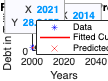


% Generate additional years for prediction
x_additional = 2023:2033;
y_additional = feval(fitObject, x_additional);

% Plot Fitted Curve
plot(Years, feval(fitObject, Years), '-r', 'LineWidth', 1.5); % Red line for the fit
plot(x_additional, y_additional, 'xr', 'MarkerSize', 8); % Red 'x' for predictions

% Add Legend
legend('Data', 'Fitted Curve', 'Predicted Trend', 'Location', 'northwest');


% Display Data Table
table(x_additional',y_additional)

ans = 11×2 table
    Var1    y_additional
    ____    ____________

    2023       32.018   
    2024       34.008   
    2025       36.069   
    2026       38.199   
    2027       40.398   
    2028       42.668   
    2029       45.007   
    2030       47.416   
    2031       49.895   
    2032       52.444   
    2033       55.062   




TT = fitObject(Years) 

TT =     5.4800
    5.8667
    6.3232
    6.8494
    7.4453
    8.1110
    8.8464
    9.6516
   10.5264
   11.4710


fT=fix(TT)

fT =      5
     5
     6
     6
     7
     8
     8
     9
    10
    11


fD=fix(Debt')

fD =      5
     5
     6
     6
     7
     7
     8
     9
    10
    11


i = fix(TT') == fix(Debt)

i = 1×24 logical array
   1   1   1   1   1   0   1   1   1   1   0   0   0   0   1   1   0   0   0   0   1   1   1   0



disp(Debt)

    5.6000    5.8000    6.3000    6.7000    7.3000    7.9000    8.5000    9.0000   10.0000   11.9000   13.5000   14.7000   16.0000   16.7000   17.8000   18.5000   19.5000   20.2000   21.5000   22.7000   26.9000   28.4000   30.9000   33.1000




table(fT,fD)

ans = 24×2 table
    fT    fD
    __    __

     5     5
     5     5
     6     6
     6     6
     7     7
     8     7
     8     8
     9     9
    10    10
    11    11
    12    13
    13    14
    14    16
    15    16
    17    17
    18    18



%14/24 = 58.33...% with a margin of error of 1
%when matching with the curve graph



